%First of all, load data 
load('./traces_v4/threshold.mat');

%Then, calculate correlations
numberOfSets = 500;
setSize = 31;
meanTraces = getMeanTraces(traces_Y,numberOfSets,setSize);

totalComparisons = (size(meanTraces,1)) * (size(meanTraces,1)-1) / 2;
category = cell(1,totalComparisons);
corr = zeros(1,totalComparisons);
inputComparison = inputs_b(1:31:size(inputs_b,1),:);

index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        corrMat = corrcoef(meanTraces(i,:),meanTraces(j,:));
        index = index + 1;
        corr(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

category = categorical(category);

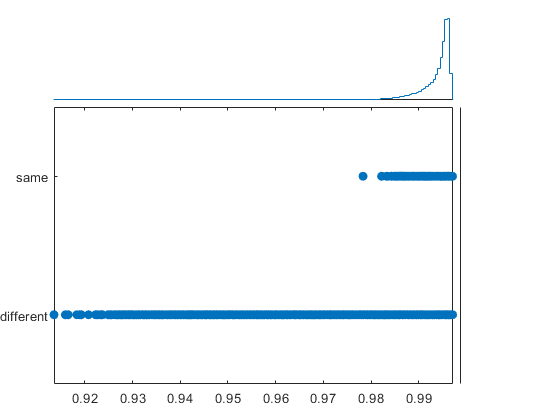

scatterhistogram(corr,category);

category2 = cell(1,totalComparisons);
dist = zeros(1,totalComparisons);

index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        index = index + 1;
        dist(index) = norm(meanTraces(i,:) - meanTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category2(index) = {'same'};
        else
            category2(index) = {'different'};
        end
    end
end

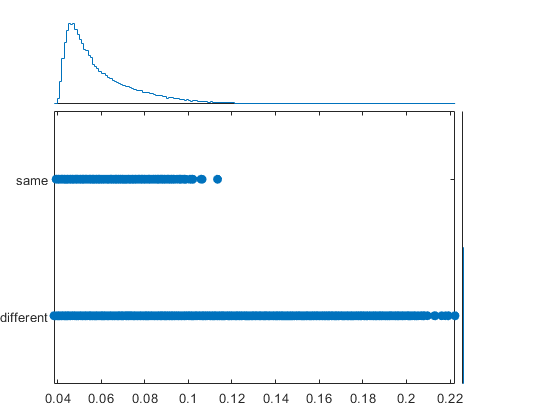

category2 = categorical(category2);
scatterhistogram(dist,category2);